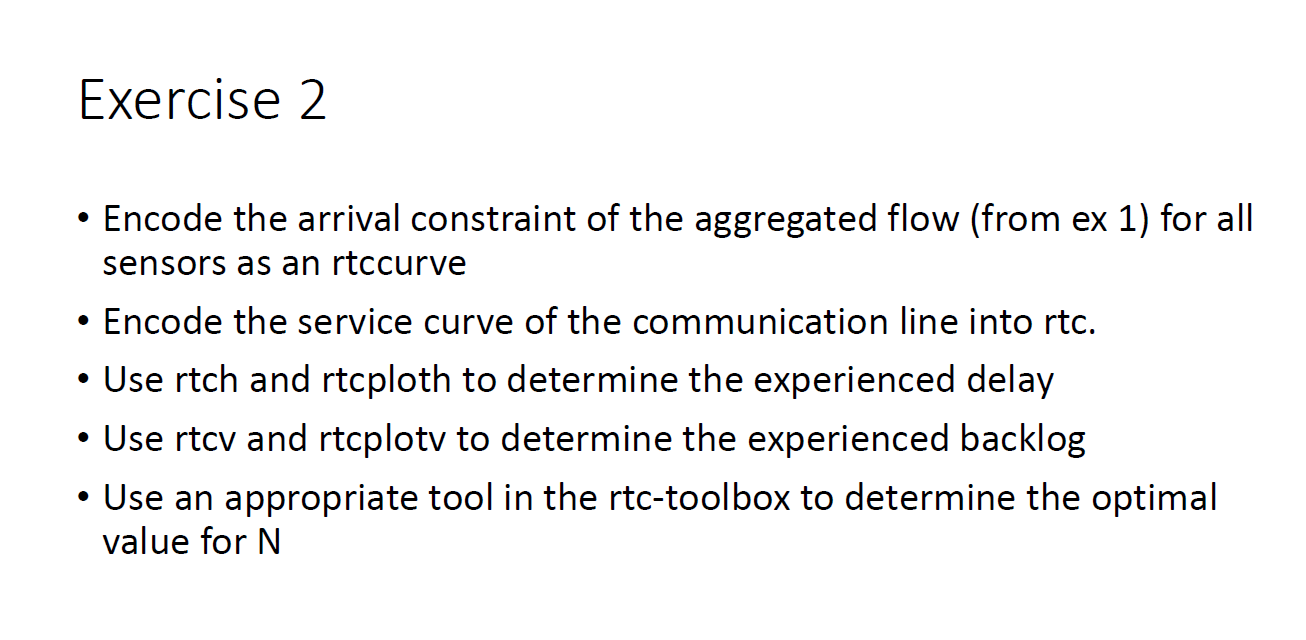

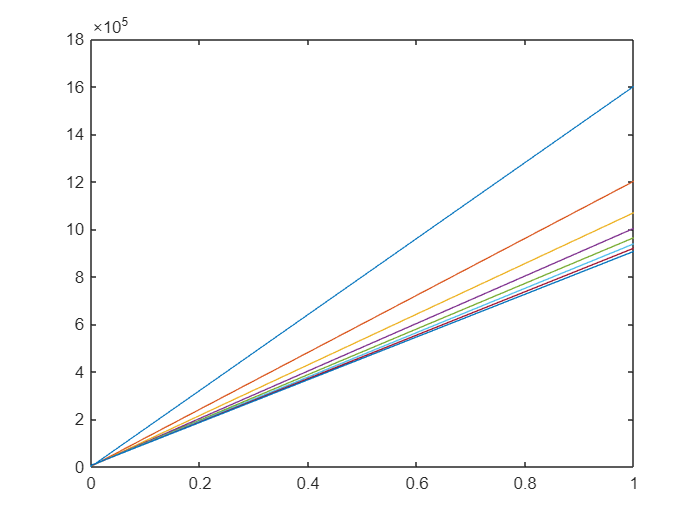

for N = 1:8
    r = 8*(100000 + 100000/N);
    burst = 8*(100*N + 100);

    alpha{N} = rtccurve([0,burst,r]);
end
rtcplot(alpha{:})

N = 5;

r = 8*(100000 + 100000/N);
b = 8*(100*N + 100)

b = 4800

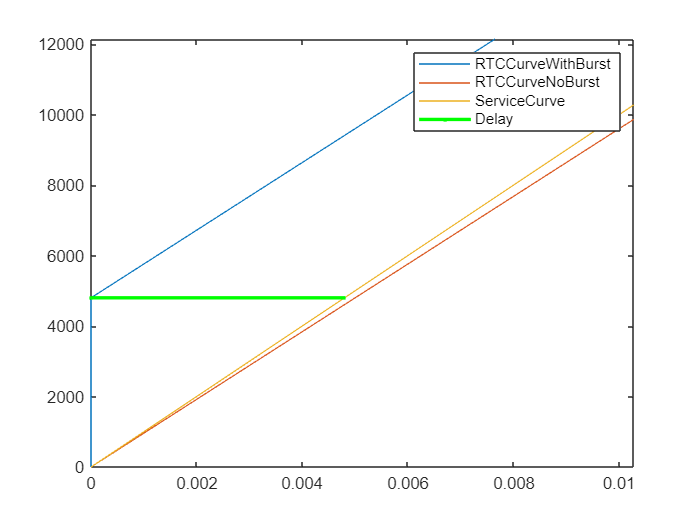


a = rtccurve([0,b,r]);
noBurst = rtccurve([0,0,r]);
beta = rtccurve([0,0,1e6]);

rtcplot(a, noBurst, beta)


D = rtch(a,beta);

rtcploth(a,beta);

legend('RTCCurveWithBurst','RTCCurveNoBurst', 'ServiceCurve', 'Delay')
xlim([0.00000 0.01028])
ylim([0 12144])

B = rtcv(a,beta)

B = 4800

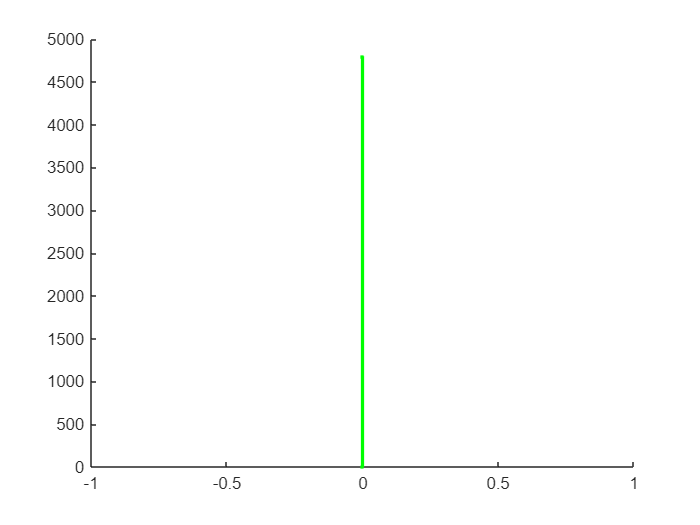

figure
rtcplotv(a,beta)

beta = rtccurve([0,0,1e6]);

Nvals = 1:20;
delay = NaN(size(Nvals));

for N = Nvals

    r = 8*(100000 + 100000/N);
    b = 8*(100*N + 100);

    % skip infeasible solutions
    if r >= 1e6
        continue
    end

    alpha = rtccurve([0,b,r]);

    delay(N) = rtch(alpha,beta);

end

[minDelay,idx] = min(delay);

optimalN = Nvals(idx)

optimalN = 5